% This models the 436 CP16 antenna .
% Parameter : Datasheet / Model
% Gain : 13.3 dBic / 13.3 dBi
% Front -to - back : 15 dB / 16.6 dB
 % HPBW : 42.0 / 48.0
d1 = dipole ('Length' ,12.625*.0254 , 'Width' , cylinder2strip((3/32)*.0254) ,...
'Tilt' ,90,'TiltAxis' ,[0 1 0]);
d2 = dipole ('Length' ,12.250*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
 'Tilt' ,90,'TiltAxis' ,[0 1 0]);
d3 = dipole ('Length',11.937*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
'Tilt' ,90,'TiltAxis' ,[0 1 0]);
d4 = dipole ('Length' ,11.750*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
 'Tilt' ,90,'TiltAxis' ,[0 1 0]);
d5 = dipole ('Length' ,11.531*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
'Tilt' ,90,'TiltAxis' ,[0 1 0]);
d6 = dipole ('Length',11.375*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
'Tilt',90,'TiltAxis' ,[0 1 0]);
r = dipole ('Length' ,13.687*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
'Tilt' ,90,'TiltAxis' ,[0 1 0]);
dip=dipole('Length',13.625*0.0254,'Width',cylinder2strip((3/32)*0.0254),...
'Tilt',90,'TiltAxis' ,[0 1 0]) ;
uhf = quadCustom('Exciter',dip,...
'Director', {d1 d2 d3 d4 d5 d6 } ,...
'DirectorSpacing', [(17 -14.562) (23.313 -17) (31.875 -23.313)...
(41.813 -31.875) (51.563 -41.813) (61 -51.563)].*0.0254 ,...
'Reflector' ,{r} ,...
'ReflectorSpacing', 2.562*0.0254 ,...
'BoomLength', 65.75*0.0254 ,...
'BoomWidth', cylinder2strip((1/2)*0.0254) ,...
'BoomOffset' ,[0 0.005 (65.75/2 -14.562)*0.0254] ,...
'Tilt' ,90 ,...
'TiltAxis' ,[0 1 0]);

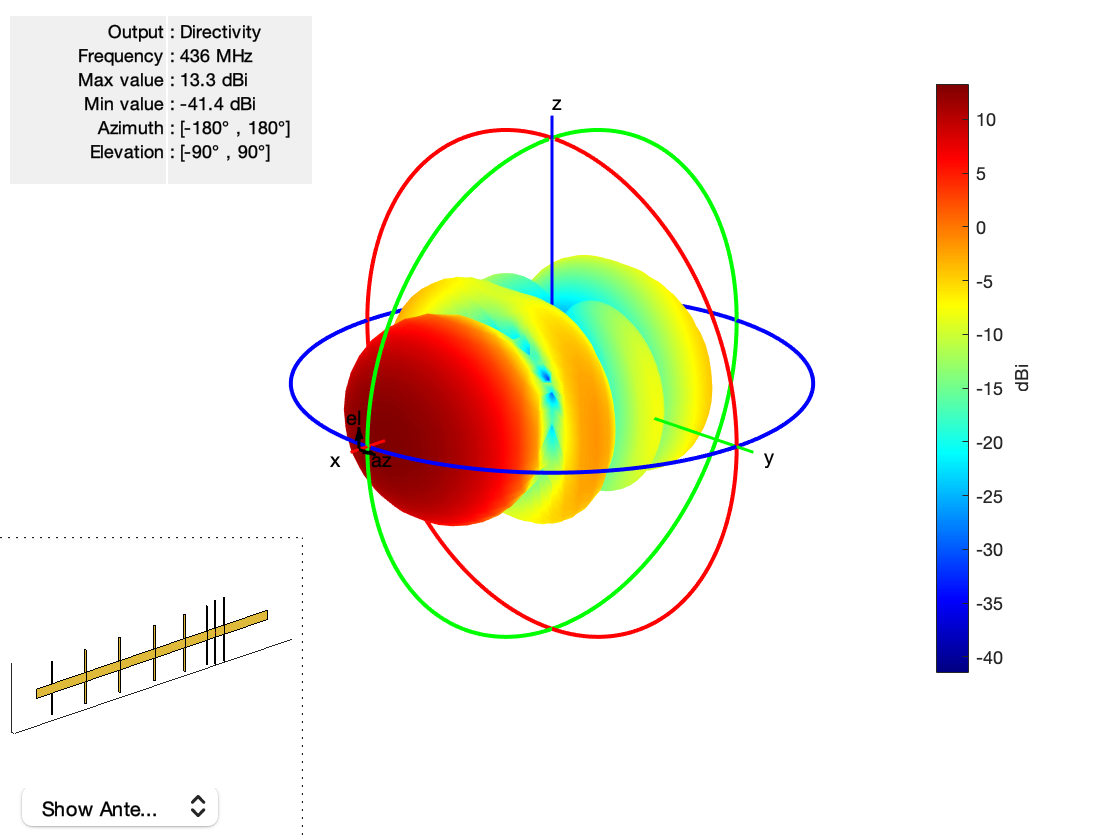

% figure
% pattern(uhf ,436e6)

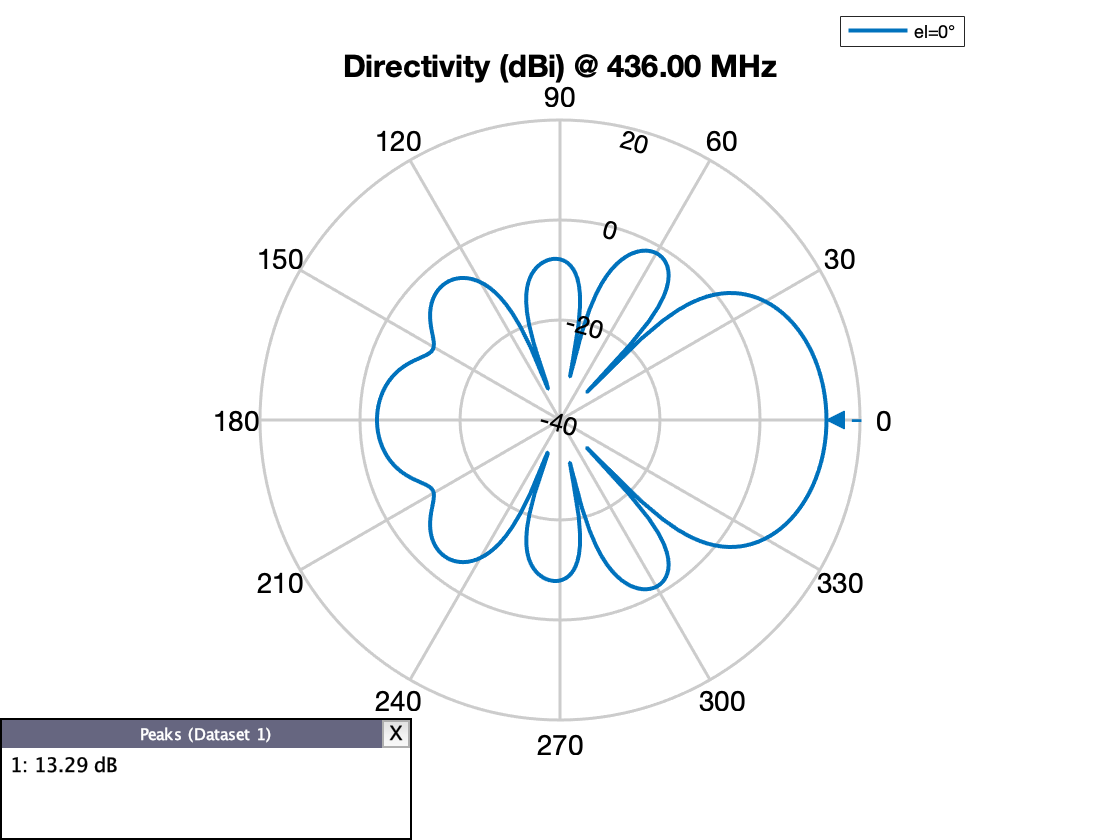

% figure
% patternAzimuth (uhf ,436e6);

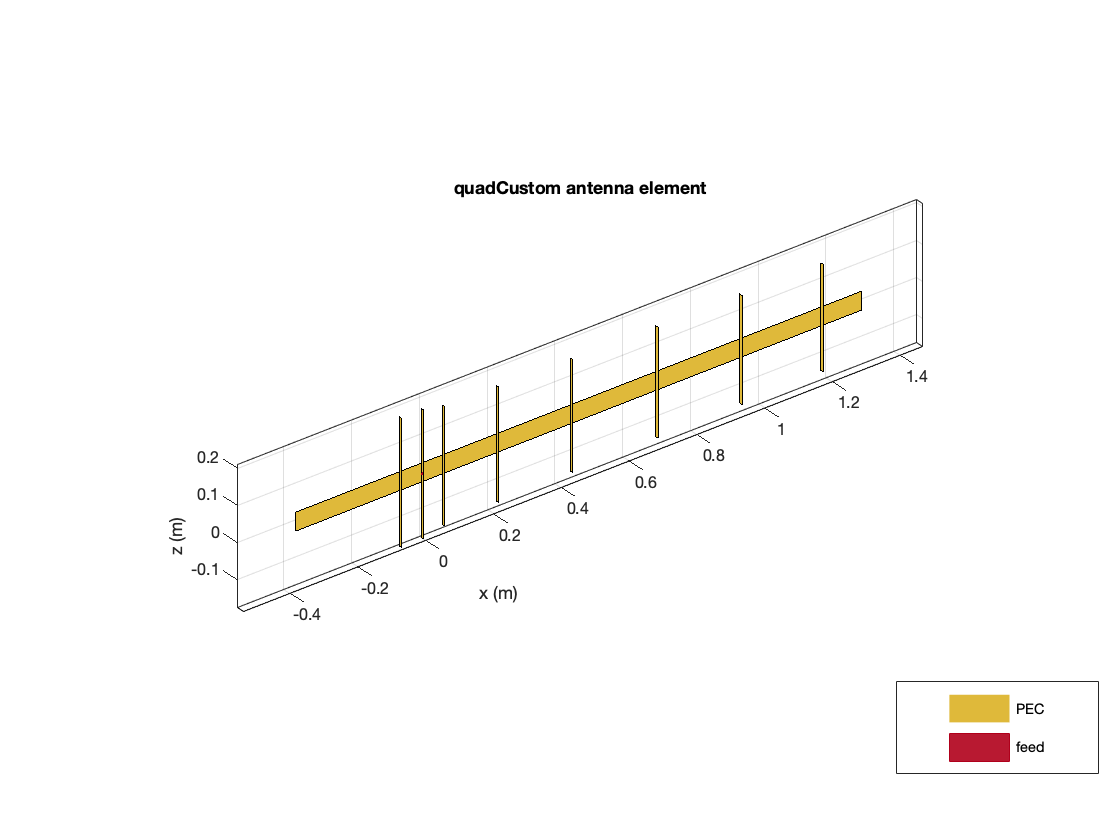

% figure
% show (uhf)

fc =435e6; % For UHF = 435e6 , f o r VHF = 146 e6
c = physconst ('LightSpeed');
ant = uhf;
wavelength = c/fc;

% coords=pseudo_array()

coords =     3.2176    0.6260    2.6644   -5.9518   -5.2621    0.9792    2.7068   -2.0973    7.7062    5.6884   -1.9796   -1.1480   -6.0702   -4.3810    1.3278   -3.3529   -3.7555    7.7226   -2.4980   -6.2757
    2.6614    3.1697   -5.1499    7.9853   -7.4784    6.1099   -4.9531   -0.6284   -5.4975    2.3162   -4.9452   -0.2876    1.4321   -1.8461   -3.9711    1.8735    5.1900    3.6840    1.3451    6.5009


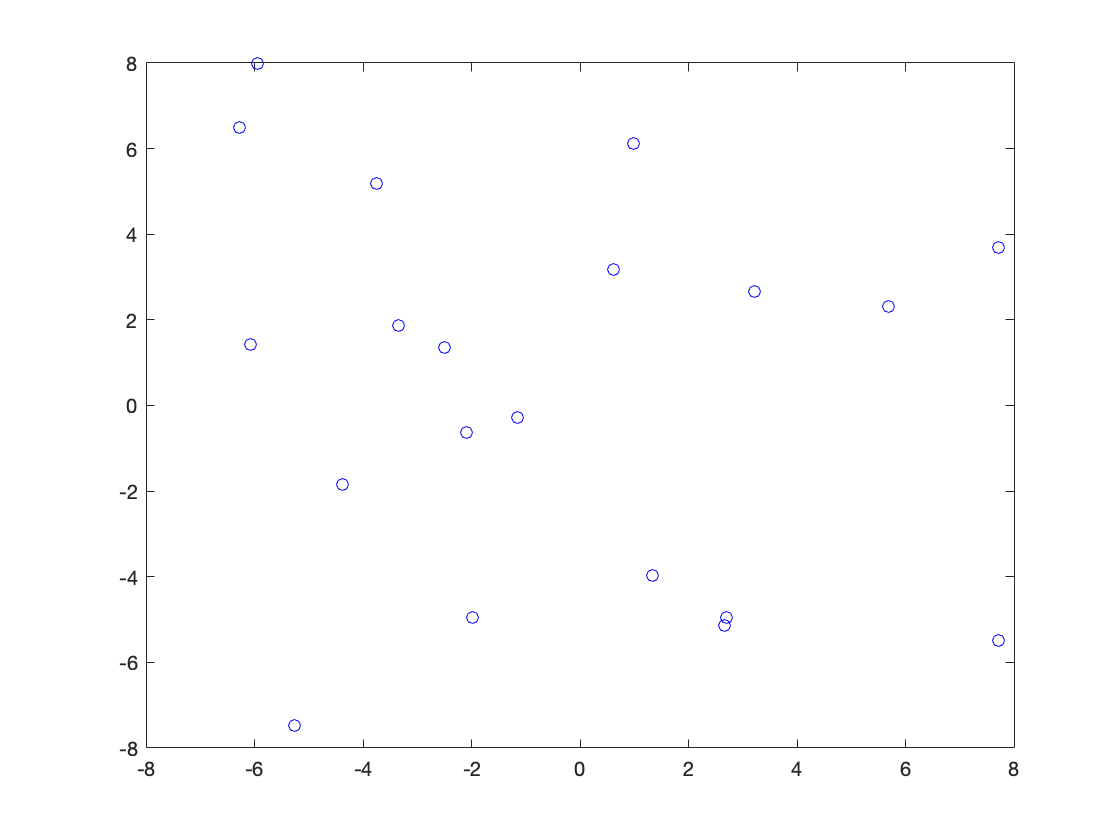

% x=coords(1,:);
% y=coords(2,:);
% figure
% plot(x,y,'bo')

[x,y]=GetPointsRandom(20,32,32,6)

x =    26.0712    4.0636   20.2355    8.9119   30.6293   13.4964   21.7195   23.7802    8.8615   30.4071   14.0398   14.2588    4.7774   29.3502    2.4273    2.5016   13.7666   29.7233    4.3697   19.6021


y =    28.9853   29.2280    3.1213   17.5002   15.5320   29.3035   24.2477   12.5513    1.4775    1.1023   12.2099   20.6820    8.2403    9.1468    1.7264   14.1657    5.9141   23.3706   23.0793   31.6784


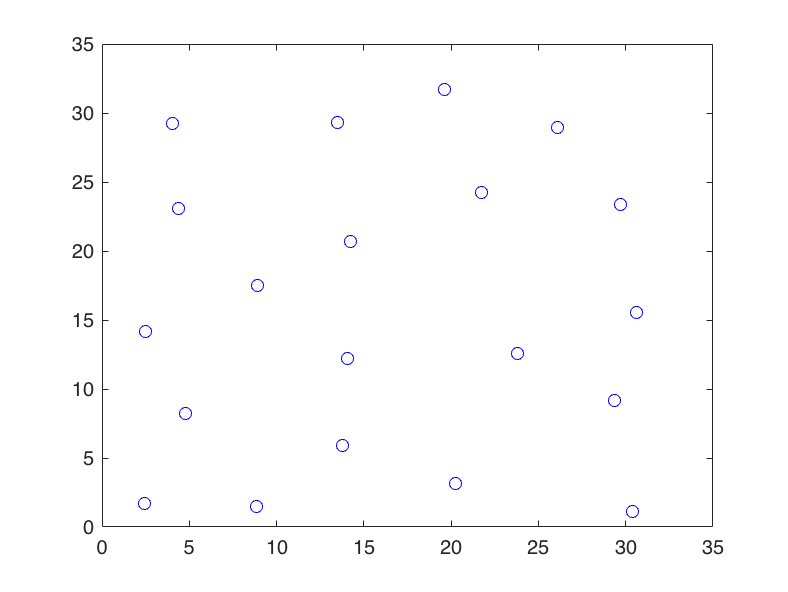

plot(x,y,'bo')

elempos=[x;y; 0 0 0 0 0 0 0 0 0 0 0 0 ...
0 0 0 0 0 0 0 0]

elempos =    26.0712    4.0636   20.2355    8.9119   30.6293   13.4964   21.7195   23.7802    8.8615   30.4071   14.0398   14.2588    4.7774   29.3502    2.4273    2.5016   13.7666   29.7233    4.3697   19.6021
   28.9853   29.2280    3.1213   17.5002   15.5320   29.3035   24.2477   12.5513    1.4775    1.1023   12.2099   20.6820    8.2403    9.1468    1.7264   14.1657    5.9141   23.3706   23.0793   31.6784
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


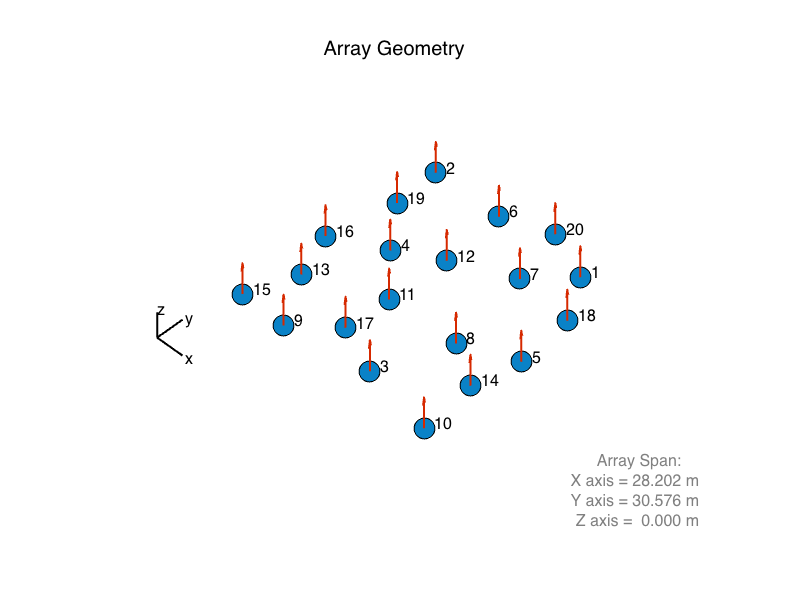


% Create an arbitrary array which takes i n custom coordinates .
arbitrary = phased.ConformalArray(...
'ElementPosition', elempos,...
'ElementNormal', [0;90] ,...
'Element',ant);
% View the array elements by uncommenting below .
figure
viewArray(arbitrary ,'showNormals',true ,'ShowIndex','All')

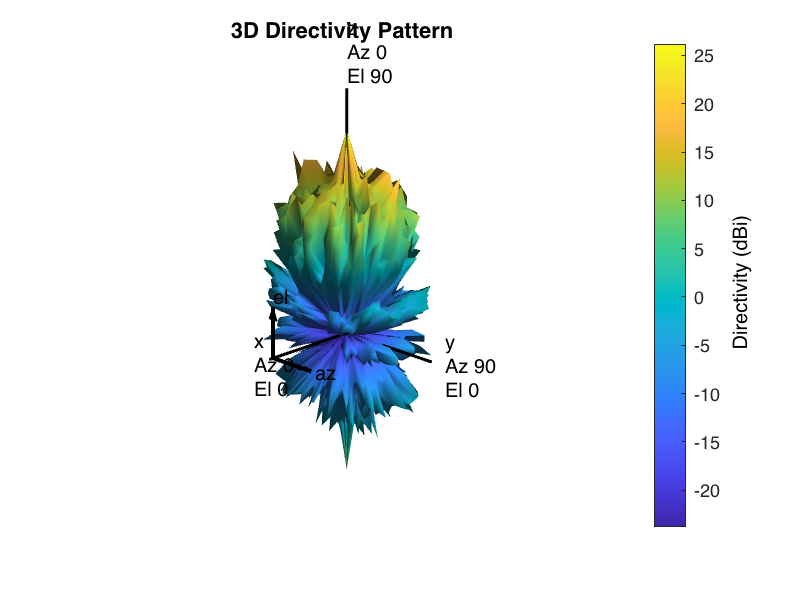

% Look at the overall array ’s beam pattern .
figure
pattern(arbitrary,fc);

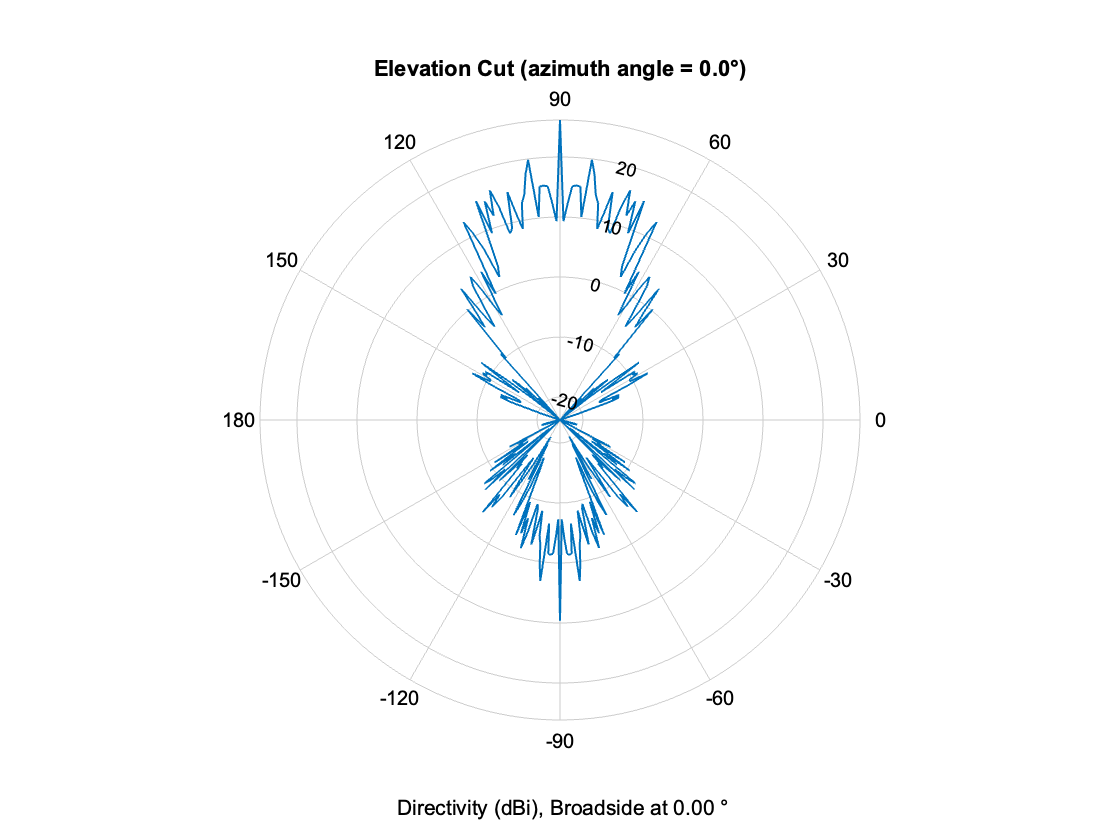

patternElevation(arbitrary,fc,0,'PropagationSpeed',c,'Type','directivity')

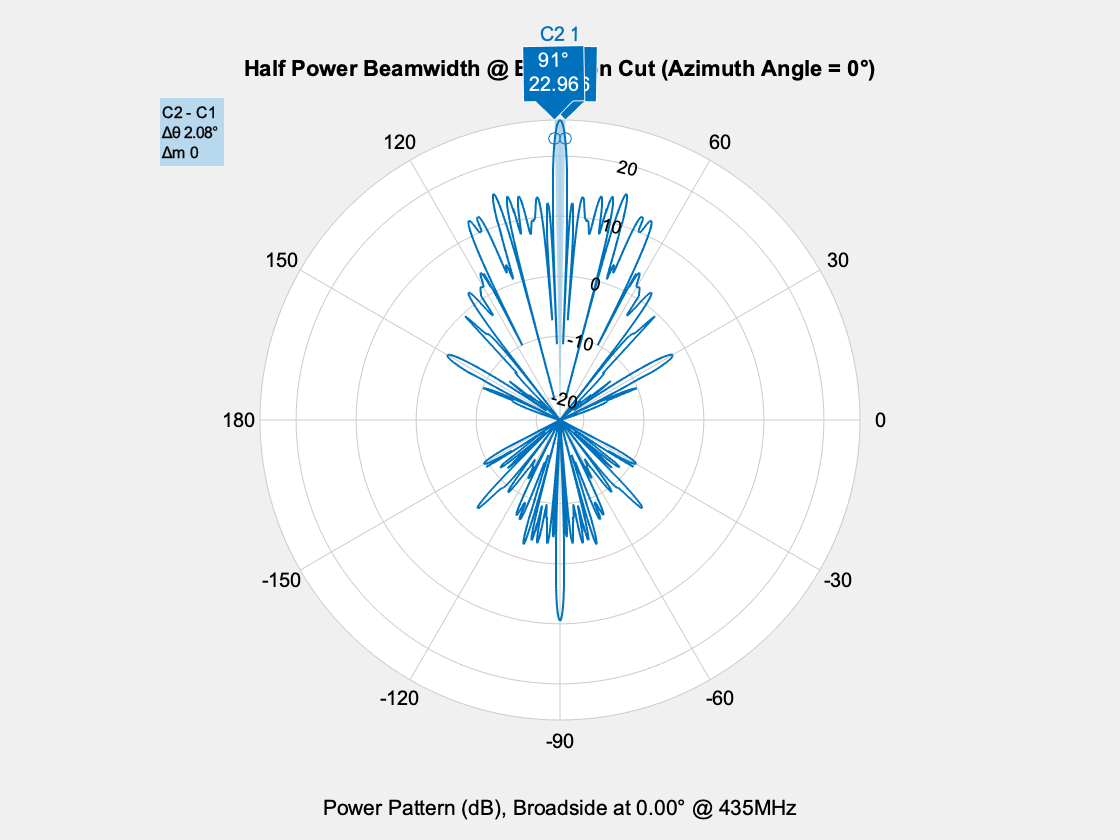

ans = 2.0800

beamwidth(arbitrary,fc,'Cut','Elevation')

[b,a]=beamwidth(arbitrary,fc,'Cut','Elevation')

b = 2.0800

a =    88.9600   91.0400


[pat,az,el]=pattern(arbitrary,fc,[-180:10:180],[-90:0.01:90],'PropagationSpeed',c, ...
    'CoordinateSystem','polar','Type','directivity');

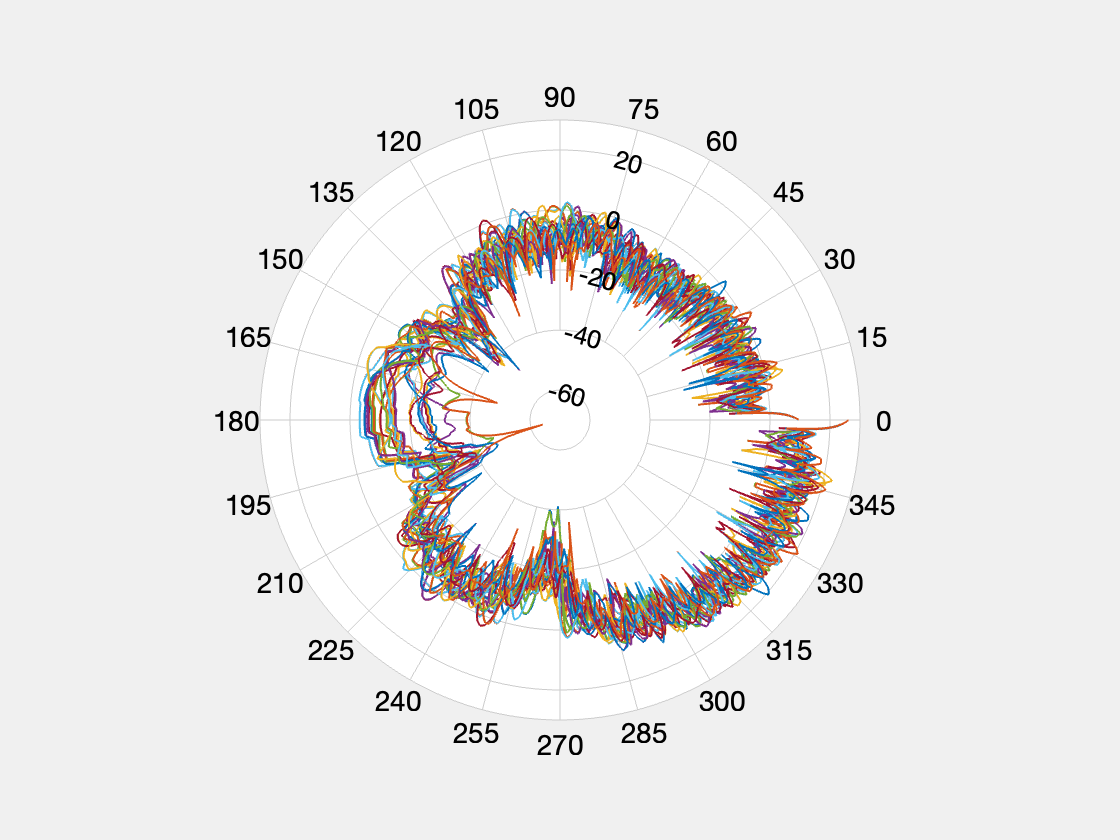

p=polarpattern(pat);

L=findLobes(p)

L = struct with fields:
     mainLobe: [1×1 struct]
     backLobe: [1×1 struct]
    sideLobes: [1×1 struct]
           FB: 65.1733
          SLL: 4.5786
         HPBW: 1.0399
         FNBW: 4.2198
        FBIdx: [18001 9.0005e+03]
       SLLIdx: [18001 17266]
      HPBWIdx: [17950 1]
      HPBWAng: [358.9601 0]
      FNBWIdx: [17896 106]


MainLobe = L.mainLobe

MainLobe = struct with fields:
        index: 18001
    magnitude: 26.1832
        angle: 359.9800
       extent: [17896 106]


SideLobe = L.sideLobes

SideLobe = struct with fields:
        index: 17266
    magnitude: 21.6046
        angle: 345.2808
       extent: [43×2 double]


BackLobe = L.backLobe

BackLobe = struct with fields:
    magnitude: -38.9901
        angle: 179.9800
       extent: [8240 9762]
        index: 9.0005e+03


MLR=MainLobe.magnitude/SideLobe.magnitude

MLR = 1.2119